# Group Project Part 3: Least Squares

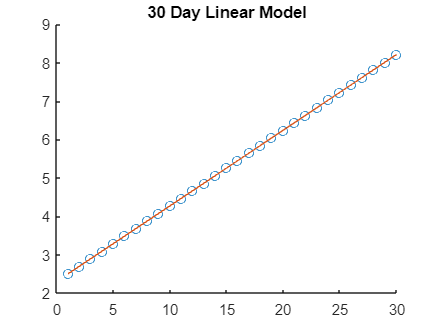

clear all
%Initial Conditions
beta = 0.3;
gamma = 0.1;
I0 = 10;
S0 = 990;
R0 = 0;
N = 1000;
k = ((beta*S0)/N)-gamma;

% Part 2
lnIt = @(t) log(I0) +(k*t);
t30 = 1:30;
a1 = (30*sum(t30.*lnIt(t30))-(sum(t30)*sum(lnIt(t30))))/(30*sum(t30.^2)-sum(t30)^2);
a0 = ((1/30)*sum(lnIt(t30)))-(a1*(1/30)*sum(t30));
scatter(t30,lnIt(t30))
hold on
title('30 Day Linear Model')
plot(a1*t30+a0)
hold off

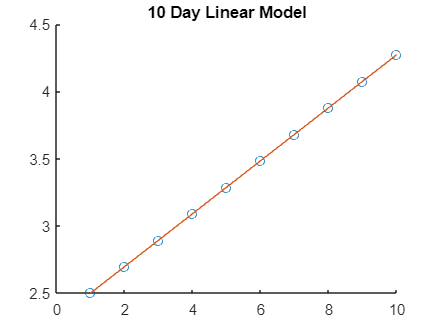


% Part 3
lnIt = @(t) log(I0) +(k*t);
t10 = 1:10;
a1 = (10*sum(t10.*lnIt(t10))-(sum(t10)*sum(lnIt(t10))))/(10*sum(t10.^2)-sum(t10)^2);
a0 = ((1/10)*sum(lnIt(t10)))-(a1*(1/10)*sum(t10));
scatter(t10,lnIt(t10))
hold on
title('10 Day Linear Model')
plot(a1*t10+a0)
hold off